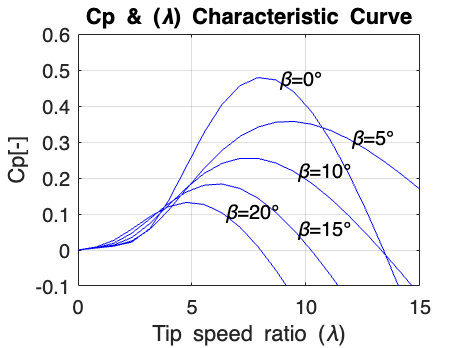

c1 = 0.5176;                       %value given 
c2 = 116;                          %value given
c3 = 0.4;                          %value given
c4 = 5;                            %value given
c5 = 21;                           %value given
c6 = 0.0068;                       %value given
Beta = [0 5 10 15 20];             %beta value for diff. angle 
Lambda = linspace(0,15,20);        %line spacing 
cpsave=[];                         % cp value save 
lamdasave=[];                      %lamda value save 

for i=1:1:5                        %loop for calling beta 
    cpsave=[];
    lamdasave=[];

    for Lamda = 0:0.1:15
        T =  1./(Lambda+0.08*Beta(i)) - (0.035./(Beta(i)^3 + 1));
        Cp = c1*(c2*T-c3*Beta(i)-c4).*exp(-c5*T)+c6*Lambda; %equation
    end
    
    cpsave=[cpsave Cp];           % save cp data for each beta values
    lamdasave=[lamdasave Lambda]; % save lamda data for each beta values
    plot(lamdasave,cpsave,'b-')   % plot for each value
    hold on                       %hold the prev plot to avoid overlap
end
                                  %Ploting graph
ylim([-0.1 0.6])
grid;
xlabel('Tip speed ratio (\lambda)')
ylabel Cp[-]
title('Cp & (\lambda) Characteristic Curve')
text(8.684,0.4723, '\beta=0°')
text(11.84,0.3094, '\beta=5°')
text(9.474,0.2178, '\beta=10°')
text(9.474,0.05477, '\beta=15°')
text(6.316,0.1033, '\beta=20°')